clc;
clear;
close all

%方程参数
L = -1;%L = 1 逆时针 L=-1顺时针

pret = 0.3; %预测时间
dt = 0.010;
%其他参数 以R标为坐标原点
radius = 700; %mm
omega = 10/60;
fn_angle = @(t) L*(omega*t);

fn_omega = @(t) L*(omega);
t0 = 1.01:dt:6.3;
angle = fn_angle(t0);
% rand72 = 0;
tiaobiantime = 2.5;
% 2.5s后随机跳变72度的整数倍
for i = 1:1:floor(t0(end)/tiaobiantime)
    ttt = (t0 - t0(1))./tiaobiantime;
    flag = i+1>ttt & ttt>i;
    rand72 = randi([1, 4])*2*pi/5;
    angle(flag) = angle(flag)+rand72;
end

theta = mod(angle, 2*pi);
theta_0 = theta(1);
% plot(t0, theta, "*")


%real
pre_index = floor(pret/dt)+2:1:length(t0);
real_x = radius*cos(theta(pre_index));
real_y = radius*sin(theta(pre_index));

pre_x = [];
pre_y = [];
r_noise = (0.1/360) * 2 * pi*randn(1,length(theta));
z_ = theta + r_noise; % 观测加噪声0.1度高斯噪声
% plot(1:length(theta),z_-theta)

aim_x = [];
aim_y = [];


for i = 2:length(theta)
    
    
    %更新
    Z = [radius*cos(z_(i));
        radius*sin(z_(i))];
    
    if length(theta)-30>=i && i>=2
        [m,n] = yunsu_predicted([Z;fn_omega(1.01)],pret);
        aim_x = [aim_x, m];
        aim_y = [aim_y, n];
    end
end



% 初始化图形并保持
figure;
hold on;

for i = 1:10:length(real_y)
    % 绘制实际点
    plot(real_x(1, i), real_y(1, i), 'ro')
    hold on 
%     plot(radius*cos(z_(i+1)),radius*sin(z_(i+1)),"g*")
% %     绘制预测点
%     plot(pre_x(1, i), pre_y(1, i), 'b+')
    plot(aim_x(1, i), aim_y(1, i), 'bx')
%     legend(["真实","观测","预测dt","预测0.5s"])
    % 暂停一段时间
    pause(0.01)
end
error = ((real_x-aim_x).^2+(real_y-aim_y).^2).^0.5;
error(error>200) = 0;
rmse = sum(error)/length(real_y);
disp([rmse,"mm"])

    "1.6742e-13"    "mm"



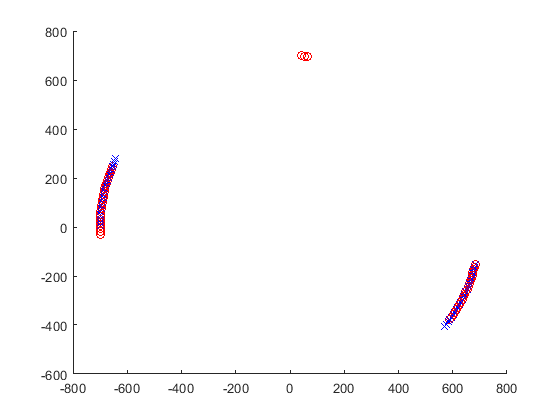

% 释放图形，以便绘制新的图形
hold off;


plot(real_x, real_y, 'ro-', 'MarkerSize', 3);
hold on;
plot(pre_x, pre_y, 'b+-', 'MarkerSize', 4);
% plot(0, 0, 'g*', 'MarkerSize', 20);
hold on;


% 设置坐标轴的标签和标题
xlabel('X Position (mm)');
ylabel('Y Position (mm)');
title('Actual vs Predicted Points');
legend("real", 'predict');

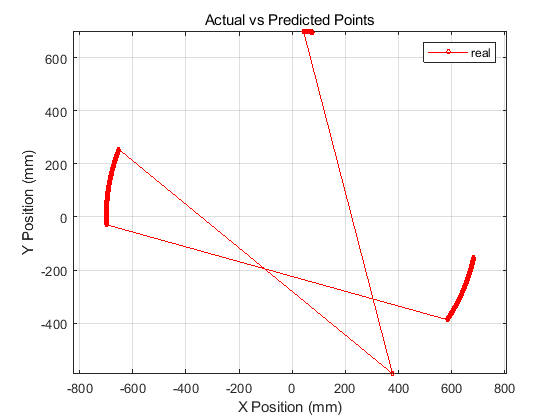


% 添加网格线
grid on;

% 设置坐标轴比例
axis equal;